# Aula 4 - Laboratório de Controle - 2021/1

## Avaliação gráfica do efeito de parâmetros na resposta ao degrau

## Nome: Yuri Rissi Negri

g2=init(3,5) % Professor, somente na hora de submeter o arquivo percebi que troquei o 

g2 =
 
         28.8
  -------------------
  s^2 + 14.4 s + 28.8
 
Continuous-time transfer function.



             % meu valor de I, não sei que confusão arrumei, era pra ser 8 e como teve
             % a parte que tive que mostrar pro senhor, achei melhor manter com o valor 
             % que fizemos em sala. Espero que não haja problema, qualquer coisa o senhor
             % pode me enviar um e-mail. yuri_rissi@hotmail.com
b0=g2.Numerator{1}(3);p0=g2.Denominator{1}(3);

## Atividade 1 - Análise do erro em regime

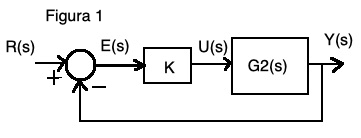

Abaixo são usados 20 valores de ganho $K$ para fechar a malha e calcular o [erro em regime ](http://www.fem.unicamp.br/~em621/aulas/aula16/analiserro.pdf)$E(s)=\frac{R(s)}{1+KG_{2}(s)}$ para uma entrada degrau unitário $R(s)$, conforme a Figura 1. 

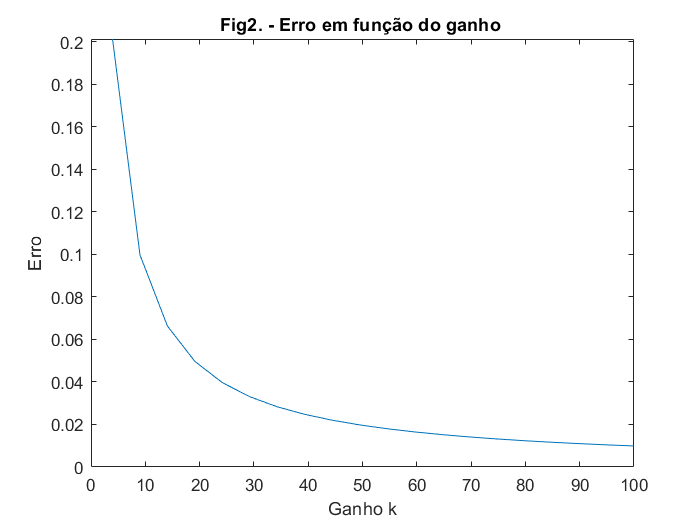

k=linspace(p0/(0.25*b0)-1/b0,p0/(0.01*b0)-1/b0,20);
for i=1:length(k)
    m=feedback(1,k(i)*g2);
    erro(i)=freqresp(m,0);
end
plot(k,erro);title('Fig2. - Erro em função do ganho ');xlabel('Ganho k');ylabel('Erro');

1.1 Qual o efeito do ganho no erro em regime? 

    Para um maior valor de ganho, vamos ter um menor erro estacionário, podemos observar pela figura 2. Porém em muitos casos, o aumento do ganho pode gerar resultados não desejados no sobresinal.

1.2 Para que valores de ganho K o erro é menor que 5%? 

    Tomando um ponto no gráfico, podemos perceber que para valores de K maior que 19, para o nosso sistema vamos ter um erro menor que 5%.  

1.3 Qual o erro em regime para sistemas com tipo igual ao de g2?

    Analisando nossa FT g2 sabemos que é um sistema de tipo 0. Assim, sabemos que para uma entrada em degrau a resposta do nosso sistema será dado por ess(t) = 1/(1 + Kp), onde Kp é definido como a constante de erro estático de posição, que é a constante de erro para uma entrada em degrau, como é o nosso caso. Então para o nosso gráfico da figura 2, os valores de K = Kp, assim podemos por exemplo tomar um ponto no gráfico onde Kp = 49 por exemplo e ver graficamente que o erro será de 2%, o que faz sentido com o resultado esperado 1/(1+ 49) = 0,02.

Na figura 3 é mostrada a resposta Y(s) ao degrau unitário R(s) bem como o erro E(s) e a integral absoluta do erro (IAE), calculada por $iae=\int_{0}^{3}|e(t)|dt$. Observe que o iae é integrado para cada tempo t. O valor utilizado para comparações é aquele obtido na janela de tempo total, ou seja, em t=3, neste caso igual a 1.25.

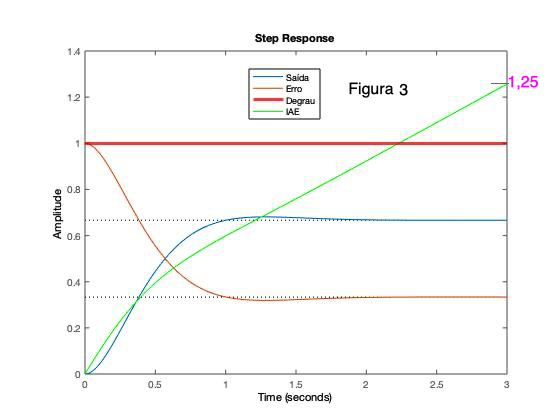

1.4 Observando as figuras 2 e 3, explique o que leva um sistema a ter maiores valores de iae.

    O aumento do IAE se dá quanto mais a entrada (linha vermelha) se afasta da saída (linha azul), tanto para o transitório quanto em regime permanente. Assim quando temos um erro na saída em regime permanente, ele irá gerar uma curva de crescimento em IAE, e quanto maior o erro, maior será a inclinação dessa curva (linha verde). 

## Atividade 2 - Erro em regime e resposta transitória

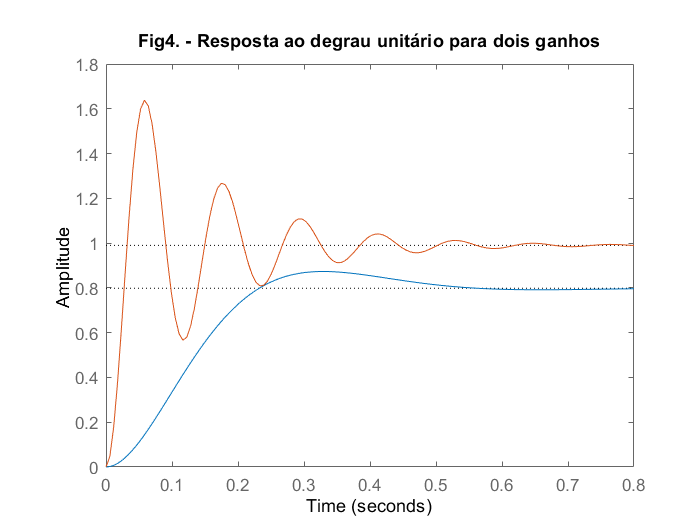

m1=feedback(k(1)*g2,1);
m2=feedback(k(end)*g2,1);
step(m1,m2);
title('Fig4. - Resposta ao degrau unitário para dois ganhos');

2.1 Na figura 4 é mostrada a resposta ao degrau unitário para o menor e maior ganhos usados na figura 2. Compare o efeito do ganho K na resposta ao degrau unitário em regime e no período transitório, informando os ganhos usados.

    Olhando o erro estacionário das duas ondas, podemos utilizar a figura 2 para estimar os valores de K utilizadas em ambos. Assim fazendo essa análise concluímos que a curva azul tem menor valor de K, sendo aproximadamente K = 4. Já a curva vermelha apresenta um menor erro, portanto um maior valor de K, sendo aproximadamente K = 100.

    Dessa forma podemos fazer algumas conclusões no efeito da saída para diferentes valores de K. Além do que já concluído anteriormente, que dizia que para maiores valores de K temos um menor erro, com o aumento de K também aumentamos a oscilação do nosso sistema e o nosso valor de sobresinal (sobreelevação). Em compensação, para maiores valores de K também temos um tempo de subida mais rápido. Porém, é interessante notar que para o nosso sistema que o aumento do K não gera quase nenhuma variação no tempo de estabelecimento, que é o tempo para o sistema atingir uma faixa de valores próxima ao valor que temos no regime permanente.

A sobreelevação se relaciona com o amortecimento $\zeta$ pela equação $UP=100 e^-({\frac{\zeta \pi}{\sqrt{1-\zeta^2}}})$. O script abaixo calcula os valores de UP para um conjunto de valores de $\zeta$.

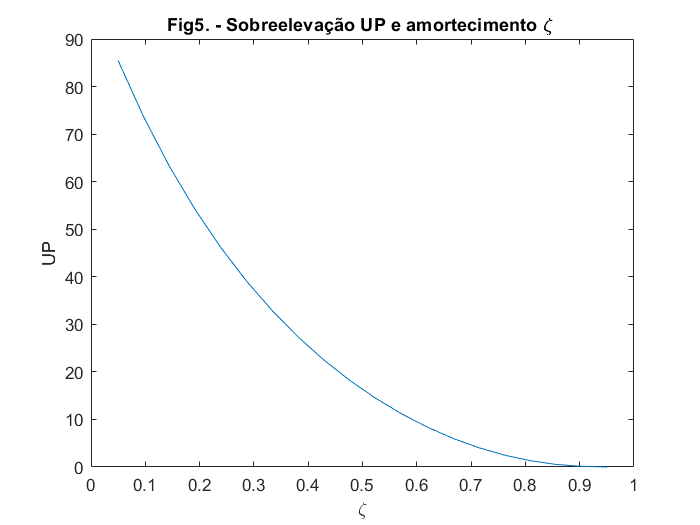

zeta=linspace(0.05,0.95,20);
for i=1:20
UP(i)=100*exp(-zeta(i)*pi/(sqrt(1-zeta(i)^2)));
end
plot(zeta,UP);title('Fig5. - Sobreelevação UP e amortecimento \zeta ');xlabel('\zeta');ylabel('UP')

2.2 Explique a relação entre UP e $\zeta$ usando a figura 5 gerada pelo script.

    Assim como na figura 2, temos uma relação inversa entre esses dois parametros. Conforme aumentamos o $\zeta$, diminuímos o valor de sobreelevação (UP).

2.3 Use a figura 5 para obter os valores de $\zeta$ para os quais se tem $UP\leq 5\%$?

    Caso desejamos ter um baixo sobresinal (sobreelevação), devemos escolher um maior valor de $\zeta$. Graficamente, para valores onde temos $\zeta$ > 0,697, teremos um valor de UP menor a 5%.

## Atividade 3 - Análise da resposta transitória

Use o comando rlocus(g2) ou rlocus(g2,k) para obter k1 de modo a ter $\zeta=0.9$ e k2 de modo a ter $\zeta=0.1$, e substitua estes valores abaixo e execute o script. 

## Importante: mostre a figura gerada pelo script abaixo ao professor antes de responder as 4 perguntas desta atividade.

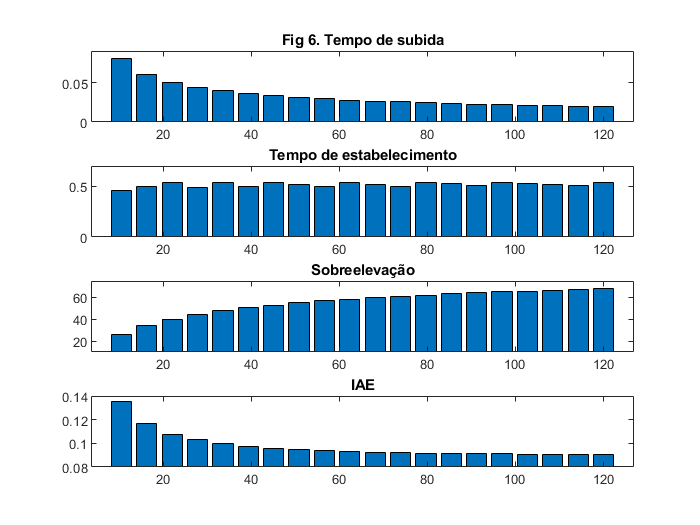

k=linspace(10.5,120,20);
for i=1:20
    m=feedback(k(i)*g2,1);
    s=stepinfo(m);
    U(i,:)=[s.RiseTime s.SettlingTime s.Overshoot];
    if i==1 
        [y,t]=step(m);Tempo=max(t);
    else
        [y,t]=step(m,Tempo);
    end
    IAE(i)=trapz(t,abs(1-y));
end

subplot(4,1,1);bar(k,(U(:,1)));title('Fig 6. Tempo de subida');ylim([0 0.09])
subplot(4,1,2);bar(k,(U(:,2)));title('Tempo de estabelecimento');ylim([0 0.7])
subplot(4,1,3);bar(k,(U(:,3)));title('Sobreelevação');ylim([10 75])
subplot(4,1,4);bar(k,(IAE));title('IAE'); ylim([0.08 0.14])

3.1 Qual o efeito do ganho K no tempo de subida ($t_r$)?

    Para maiores valores de K temos um tempo de subida mais rápido, ou seja, nossa saída irá atingir 90% do seu valor de regime mais rapidamente do que para um menor valor de K.

3.2 Qual o efeito do ganho K na sobreelevação (UP)?

    Assim como observado na figura 4, vamos obter maiores valores de sobreelevação conforme submetemos ao nosso sistema uma maior valor de K.

3.3 Explique o comportamento do tempo de estabelecimento ($t_s$) quando o ganho K varia.

    Como citado, diferentes valores de K não apresentam diferença significativa quando se diz respeito ao tempo de estabelecimento. Isso se dá pelo fato de que o tempo de estabelecimento só esta relacionado com a componente real dos nossos pólos no LGR. Podemos perceber que quando variamos o valor de K para o nosso sistema, estamos apenas alterando a parte imaginária do pólo e sua parte real no plano permanece constante, mantendo o mesmo valor de $t_s$. 

3.4 Quem afeta mais o valor de IAE? UP, $t_r$ ou $t_s$?

   Olhando para o gráfico de barras fica fácil de perceber que $t_r$ (tempo de subida) tem maior influência no valor de IAE. Como o IAE leva em consideração também o erro do transitório, graficamente basta pensar no resultado que um tempo maior para se atingir 90% do nosso valor de regime irá causar. Isso resultara em uma maior diferença entre a nossa entrada e saída por um período maior de tempo, fazendo com que nossa integral tenha um maior valor. Esse aspecto será muito mais significante do que os outros parâmetros analisados.

datetime('now')

ans = datetime
   03-Jun-2022 06:05:42


pwd

ans = 'C:\Users\diona\OneDrive\Área de Trabalho\ufes\Laboratorio de Controle Automático\Lab de Controle\Lab de Controle\Aula4'